clear all
close all
clc

filename = 'G31225.csv';
M = [csvread(filename)];
load('medidas.mat')
load('clutter.mat')
lat_gaiv = -23.562432;
long_gaiv = -46.741251;
lat = M(:,4);
long = M(:,5);

Conversão para radianos

% lat = lat-2*lat; % utilizando os sinais para indicar lat sul
% long = long -2*long; % longitude oeste

Calculando as distâncias

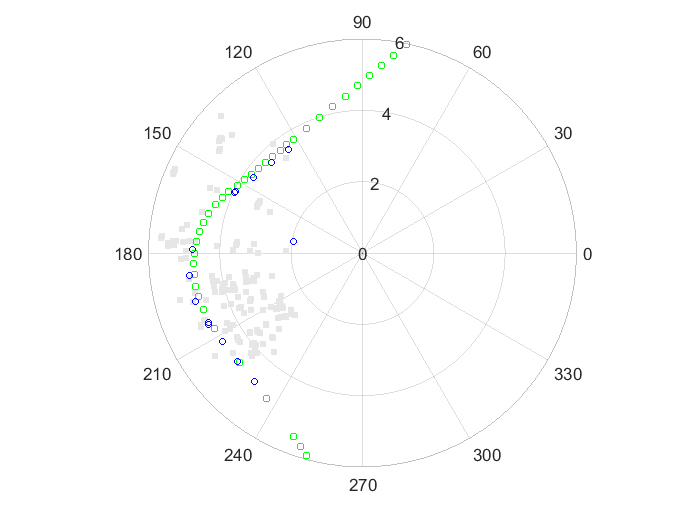

close all
d = zeros(size(lat,1),1);
azmt = zeros(size(lat,1),1);
for k=1:size(lat,1)
    delta_lat = lat_gaiv-lat(k);
    delta_long = long_gaiv-long(k);
    d(k) = sqrt((delta_lat*111.111)^2+(delta_long*111.111)^2);
    azmt(k) = atan2(delta_lat,delta_long);
end
idx = [];
for k=1:size(d,1)
    if d(k)< 10
        idx = [idx;k];
    end
end
d = d(idx);
azmt = azmt(idx)-0.47*pi;

close all
sz = 100; c = [0.9 0.9 0.9]; format = '.';
polarscatter((clutter(:,3)/3750+0.6)*pi, (clutter(:,5)*0.75+1600)/1000, sz, c,format)
rlim([0 6])
hold on
sz = 15; c = [0 1 0]; format = 'square';
polarscatter(azmt(:,1),d(:,1), sz, c, format)
hold on

sz = 15; c = [0 0 1]; format = 'o';
for k=1:size(medidas,1)
    if medidas(k,9) > 13
        break
    end      
    polarscatter((medidas(k,3)/3750+0.6)*pi, (medidas(k,5)*0.75+500)/1000, sz, c, format)
end